clc;
clear all;


Qbatt = 3600;  % A.sec of the battery   #1 Ahr=3600 As\n",
nx = 5;
nu = 1;
N = 2;
Q_mpc = zeros(5);
Q_mpc(1,1) = 1;
R_mpc = 1;
dt = 1; %sample time sec

%Initial Conditions

x_in = [0.2 0 0 297 297 8e-3]';
u_in = 0;


%Constraints
lbx = [0.1 -4.2 -4.2 253 253 0]';
ubx = [1 4.2 4.2 323 323 0.1]';
lbu = -2*ones(N,1);
ubu = 2*ones(N,1);


X_plant = [x_in];  %for plotting
X_ekf = [x_in];
U_mpc = [];
U_plant = [];


%EKF model Initialization
[F_jacobian, H_jacobian] = Jacobian();
P_ekf = 0.0001*rand(5);
x_ekf = x_in;
Q = diag([1e-5,1e-2,1e-2,1e-1,1e-1,1e-4]);
R = 1e-4;


%Plant model Initialization
I = u_in(1);
SOC = x_in(1);
V1 = x_in(2);
V2 = x_in(3);
Tc = x_in(4);
Ts = x_in(5);
R0 = x_in(6);
X_plot = [SOC;V1;V2;Tc;Ts;R0];
x_state = x_in;
Y = [];
exitflag=[];

options = optimoptions('fmincon', 'Algorithm', 'interior-point', ...
            'MaxFunctionEvaluations',1e6, 'MaxIterations',1e6, ...
            'EnableFeasibilityMode',true, 'SubproblemAlgorithm','cg', ...
            'Display','off');

%EKF Model
f = @(x,u,n)dynamics(x,u,n);  %discrere dynamics with dt = 1sec
h = @(x,v,u,n)meas_model(x,v,u,n);
ekf_object = extendedKalmanFilter(f,h,x_in,'HasAdditiveMeasurementNoise',false);  
v = [2e-1; 1e-1];
ekf_object.MeasurementNoise = diag(v);
R0_plot = [];
SOH = [1];
TAIR = [297];

%Constraint tightening 
%Get new constraints using Gaussian approximation of the process noise
%and measurement noise
beta = 0.99;
% [lbx, ubx, lbu, ubu] = getTightenedConstraints(lbx, ubx, lbu, ubu, Q, R, beta);
        

M = 1;
for m = 0:M-1
    I = u_in(1);    SOC = x_in(1);    V1 = x_in(2);    V2 = x_in(3);    Tc = x_in(4);    Ts = x_in(5);
    %MPC Loop
    Ntot = 1700;
    mpciter = 0;
    while mpciter < Ntot
        [R00, R1, C1, R2, C2, Rc, Cc, Rs, Cs, Tair] = getParameters(SOC, Tc, I,m*Ntot+mpciter);
        %     params = [R0, R1, C1, R2, C2, Rc, Cc, Rs, Cs, Tair];
        Vocv = 14.7958*SOC^6-36.6148 * SOC^5 + 29.2355 * SOC^4 -6.2817 * SOC^3 - 1.6476 * SOC^2 + 1.2866 * SOC + 3.4049;
        y_meas = [Vocv-V1-V2-I*R0; Ts];
        Y = [Y y_meas];

        %%MPC
        %Initialization for optimization variables
        if mpciter == 0
            x0 = zeros(N,1);   %u_0 ... u_n-1
        else
            x0=x;
        end

    
       

        nonlcon = @(x)nonLinearConstraints(x,x_ekf,N,lbx,ubx,m*Ntot+mpciter);
        [x, fval, ef] = fmincon(@(x)obj(x,x_ekf,Qbatt,Q_mpc,R_mpc,N), x0, [], [], [], [], lbu, ubu, nonlcon, options);
        u_in = x(1);
        exitflag = [exitflag ef];

        % Plant model
        u_plant = u_in + normrnd(0,1e-4);
%         u_plant = min(u_plant, 0); 
        Vbatt = Vocv - V1- V2 - R0*u_plant;

        SOC = SOC - u_plant/Qbatt;
        V1 = V1 - (1/(R1*C1))*V1 + (1/C1)*u_plant;
        V2 = V2 - (1/(R2*C2))*V2 + (1/C2)*u_plant;
        Tc = Tc + (V1*u_plant + V2 * u_plant + R00*u_plant^2)/Cc + 1/(Rc*Cc) * (Ts-Tc);
        Ts = Ts + (Tair - Ts)/(Cs*Rs)-(Ts-Tc)/(Cs*Rc);
        
        w = [normrnd(0, 1e-2);normrnd(0,1e-2);normrnd(0,1e-2);normrnd(0,1e-1);normrnd(0,1e-1);normrnd(0,1e-4)];
        x_state = [SOC;V1;V2;Tc;Ts;R0]+w;
        x_state(1)=min(x_state(1), 1);
        x_state(1)=max(x_state(1),0);

        %EKF estimator
        [x_pred, P_pred] = predict(ekf_object,u_in,m*Ntot+mpciter);
        [x_ekf, P_ekf] = correct(ekf_object,y_meas, u_in,m*Ntot+mpciter);
        x_ekf(1)=min(x_ekf(1),1.001);
        x_ekf(1)=max(x_ekf(1),0);

        %Data output
        U_mpc = [U_mpc u_in];
        U_plant = [U_plant u_plant];


        X_plant = [X_plant,x_state];
        X_ekf = [X_ekf, x_ekf];


        mpciter = mpciter + 1;
        TAIR = [TAIR Tair];
    end

%     x_in = [0.3 -0.1 -0.1 297 297 R0]';
%     x_ekf = x_in;
%     x_state = x_in;
%     ekf_object.State = x_in;
%     R0_plot =[R0_plot, R0];
%     soh = SOH_Estimation(Tc, u_plant);
%     SOH = [SOH soh];
%     P_ekf = 0.0001*rand(5);
end

% t = 1:M*Ntot+1;
% figure(1)
% plot(t, X_plant(1,:))
% hold on
% plot(t, X_ekf(1,:))
% hold off
% ylim([0 2])
% % xlim([0 50])
% legend('soc', 'soc_ekf');
% grid
% 
% figure(2)
% plot(t, X_plant(2,:), t,X_plant(3,:), t, X_ekf(2,:), t, X_ekf(3,:))
% ylim([-1 1])
% % xlim([0 50])
% grid
% figure(3)
% plot(t,X_plant(4,:), t,X_plant(5,:),t,X_ekf(4,:), t, X_ekf(5,:), t, TAIR)
% hold off
% % xlim([0 50])
% legend('tc','ts','tc_ekf','ts_ekf', 't_amb');
% grid
% 
% t = 1:M*Ntot;
% figure(4)
% plot(t, U_mpc, t, U_plant);
% legend('U_mpc','U_plant');
% 
% ylim([-5 5])
% % xlim([0 50])
% grid


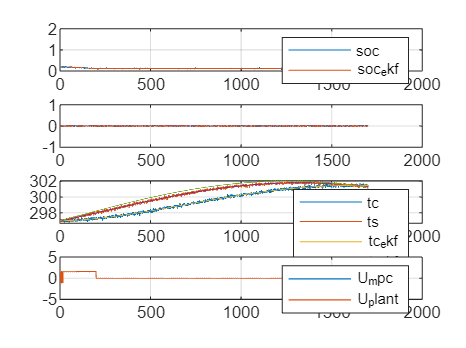

t = 1:M*Ntot+1;
figure(1)
subplot(4,1,1);
plot(t, X_plant(1,:))
hold on
plot(t, X_ekf(1,:))
hold off
ylim([0 2])
% xlim([0 50])
legend('soc', 'soc_ekf');
grid

subplot(4,1,2);
plot(t, X_plant(2,:), t,X_plant(3,:), t, X_ekf(2,:), t, X_ekf(3,:))
ylim([-1 1])
% xlim([0 50])
grid

subplot(4,1,3);
plot(t,X_plant(4,:), t,X_plant(5,:),t,X_ekf(4,:), t, X_ekf(5,:), t, TAIR)
hold off
% xlim([0 50])
legend('tc','ts','tc_ekf','ts_ekf', 't_amb');
grid

t = 1:M*Ntot;
subplot(4,1,4);
plot(t, U_mpc, t, U_plant);
legend('U_mpc','U_plant');

ylim([-5 5])
% xlim([0 50])
grid

function cost = obj(x, x_ekf, Qbatt, Q, R, N)
    SOC = x_ekf(1);
    Tc = x_ekf(4);
    Ts = x_ekf(5);
    Tref = 297;
    cost = 0;
    for i = 1:N
        cost = cost + (1-SOC)^2;  %(Tc-Tref)^2+(Ts-Tref)^2;
        SOC = SOC - 1/Qbatt * x(i);
    end
end

